Question 5 Hilbert Matrix

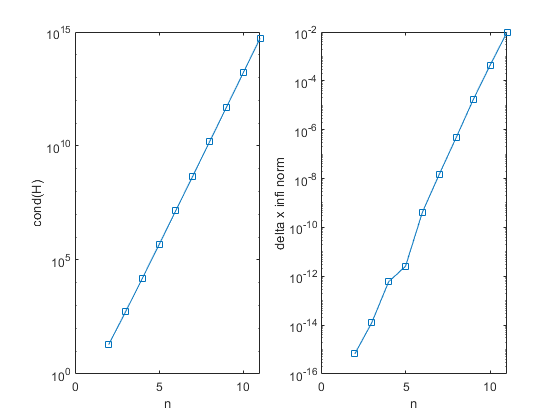

A=(zeros(3,11));
for n = (2:1:12)
    a=hilbert(n);
    x0=ones(n,1);
    b=a*x0;
    c=gauss_elimination(a,b);
    A(1,n)=n; %to store value of n
    A(2,n)=cond(a); %to store cond(H)
    A(3,n)=norm(c-x0, inf); % find inf norm of delta x
end

subplot(1,2,1)
plot(A(1,1:11),A(2,1:11), '-s')
set(gca, 'YScale', 'log')

subplot(1,2,2)
plot(A(1,1:11),A(3,1:11), '-s')
set(gca, 'YScale', 'log')

subplot(1,2,1)
xlabel('n')
ylabel('cond(H)')
subplot(1,2,2)
xlabel('n')
ylabel('delta x infi norm')

function x = hilbert(n)
x = (n:n);
for i = 1:n
    for j = 1:n
        x(i,j) = 1/(i+j-1);
    end
end
end